clear variables; clc;

s = load("lab5_3.mat");

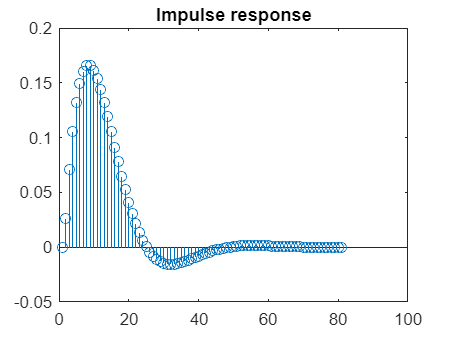


id = struct("u",s.id.InputData,"y",s.id.OutputData,"t",s.tid);
val = struct("u",s.val.InputData,"y",s.val.OutputData,"t",s.tval);

%% Identification data
id.u = detrend(id.u);
id.y = detrend(id.y);

stem(s.imp); title('Impulse response');

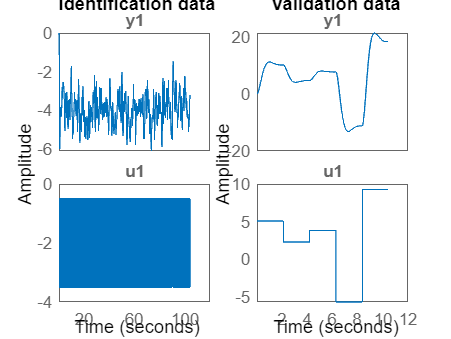

figure, 
subplot(1,2,1);plot(s.id); title('Identification data');
subplot(1,2,2);plot(s.val); title('Validation data'); 
hold off; 

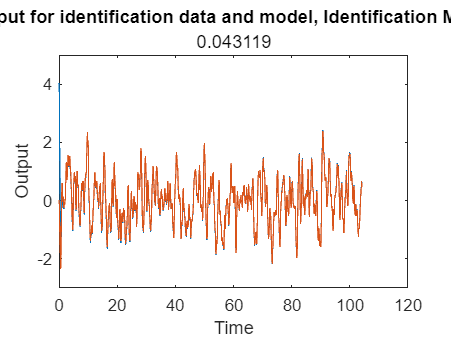


m = 70;

ru = zeros(1,length(id.u));
ryu = zeros(1,length(id.u));

for tau = 1:length(id.u)
    for k = 1:length(id.u)-tau+1
        ryu(tau) = ryu(tau)+1/length(id.u)*(id.y(k+tau-1)*id.u(k));
        ru(tau) = ru(tau)+1/length(id.u)*(id.u(k+tau-1)*id.u(k));
    end
end

Ru = zeros(length(s.id),m);

for i = 1:length(id.u)
    for j = 1:m
        Ru(i,j) = ru(abs(i-j)+1);
    end
end

Ryu = ryu.';
H = Ru\Ryu; % weighting function
ycap = conv(id.u,H);
ycap = ycap(1:length(id.t));

mse_id = 1/length(id.u)*sum((ycap-id.y).^2);

figure, 
plot(id.t,id.y,id.t,ycap); title('Output for identification data and model, Identification MSE = ',num2str(mse_id));
xlabel('Time'); ylabel('Output');

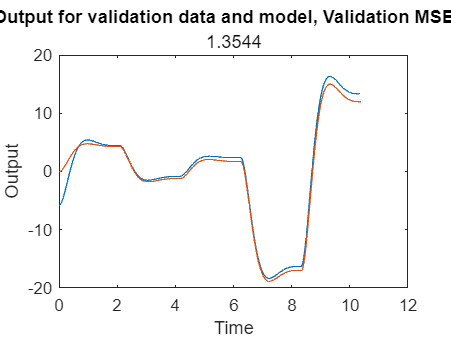


%% Validation data
val.u = detrend(val.u);
val.y = detrend(val.y);

yvalcap = conv(val.u,H);
yvalcap = yvalcap(1:length(val.t));

mse_val = 1/length(val.u)*sum((yvalcap-val.y).^2);

figure, 
plot(val.t,val.y,val.t,yvalcap); title('Output for validation data and model, Validation MSE = ',num2str(mse_val));
xlabel('Time'); ylabel('Output');